# TP2 Analyse - Transformées de Fourier

*Le compte rendu est à rédiger directement dans ce document avec votre code que vous pourrez executer à partir de ce fichier section par section.*

*Il vous est demandé de montrer les résultats, de les analyser et les interpréter tout en répondant aux questions. Nous jugerons vos capacités à comprendre et interpréter mathématiquement les réalisations. *

***Assurez-vous toujours de la lisibilité de vos figures : intitulés des axes, légende, échelle, etc***  

## Partie A - Transformée de Fourier 1D et application

### 1- Mise en place des signaux d'étude

Pour générer sur N = 2000 points un signal sinusoïdal de fréquence F0 = 20Hz échantillonné à une fréquence Fe = 8kHz et d’amplitude 1, on s’impose de créer les variables **Fe**, **Te **et **N**, ainsi que les vecteurs **t **et **sinus1**. Un programme Matlab qui réalise ces fonctions se trouve ci-dessous. Executez la section (à partir de la barre d'outils ou avec ctrl+entrée) pour le tester. 

F0 = 20;
Fe = 8000;
Te = 1/Fe;
N = 2000; % selection de la taille NE PAS MODIFIER LE CODE
t = [-N/2 : ((N/2)-1)]/Fe;
sinus1 = sin(2*pi*F0*t);
figure
plot(t,sinus1)
title('Signal sinusoidal')
xlabel('Temps') ; ylabel('Amplitude')

### 2- Calcul de la FFT (Fast Fourier Transform)

Prévoir la forme du spectre du signal construit. **Justifier**  

*****************************************************************************************************************

***VOTRE REPONSE ICI***

A l'aide de la commande fft de Matlab, calculer la TFD (transformée de Fourier Discrète) du signal. Cette commande effectue des calculs sur une matrice (celle du sinus) et donne en résultat une matrice de même taille, qui suppose un spectre entre 0 et Fe. 

%*******************************************************************************
% écrire ici l'instruction qui calcule la fft sur le signal calculé précedemment
%*******************************************************************************




Visualiser le **module** de la TFD calculée en fonction de la fréquence.  L’échelle des fréquences est donc à fabriquer de la même façon que l’on a fabriquée une échelle de temps pour accompagner les sinus. La commande *linspace *peut aider à la fabrication de cette échelle.

La commande *stem *s’utilise comme la commande *plot*. Elle permet de tracer une ligne verticale à l’endroit de chaque échantillon. On peut ainsi éviter de confondre une décroissance linéaire et une interpolation entre 2 échantillons.

Pour afficher seulement une zone de la figure, on peut utiliser l’instruction  

%*************************************************************************************
% écrire ici le code qui fabrique l'échelle de fréquence et trace le module de la TFD
%*************************************************************************************




**Expliquer **le tracé obtenu

******************************************************************************************************************

***VOTRE REPONSE ICI***

Pourquoi ne va-t-on pas au-delà de Fe ? Est-ce que la valeur en Fe est calculée (le résultat est-il sur [0,Fe] ou [0,Fe[) ?  

******************************************************************************************************************

***VOTRE REPONSE ICI***

Modifier la valeur de N en utilisant la liste déroulante du code de la première section pour générer des signaux sinusoïdaux de taille 8000 et 40000 échantillons, puis visualiser leur spectres.

Pour chaque taille d’échantillon, donner la résolution en fréquence de la FFT, et **commenter**. Observer l’amplitude des raies de chaque spectre **et conclure en justifiant**.  

******************************************************************************************************************

***VOTRE REPONSE ICI***

### 3- Qualité des relevés expérimentaux

En réalité lorsqu’on effectue des mesures expérimentales, on commence l’acquisition du signal à un instant t1 et on s’arrête à un instant t2. On n’a jamais le signal complet manipulé dans la partie précédente (un signal commençant à zéro avec un nombre entier de périodes). Le signal ainsi enregistré peut être représenté comme étant le signal de départ coupé par une porte.  

Commençons par construire un signal sinusoïdal de fréquence 20 Hz et de grande taille (N=8000). Ce signal représentera le signal réel que l’on souhaite observer et dont on fera l’acquisition sur 4096 points. Une façon de simuler cette acquisition est de multiplier le signal de départ par une porte (signal égal à 0 partout sauf sur les 4096 points de l’échantillon où il est égal à 1) . La figure ci dessous en montre un exemple.

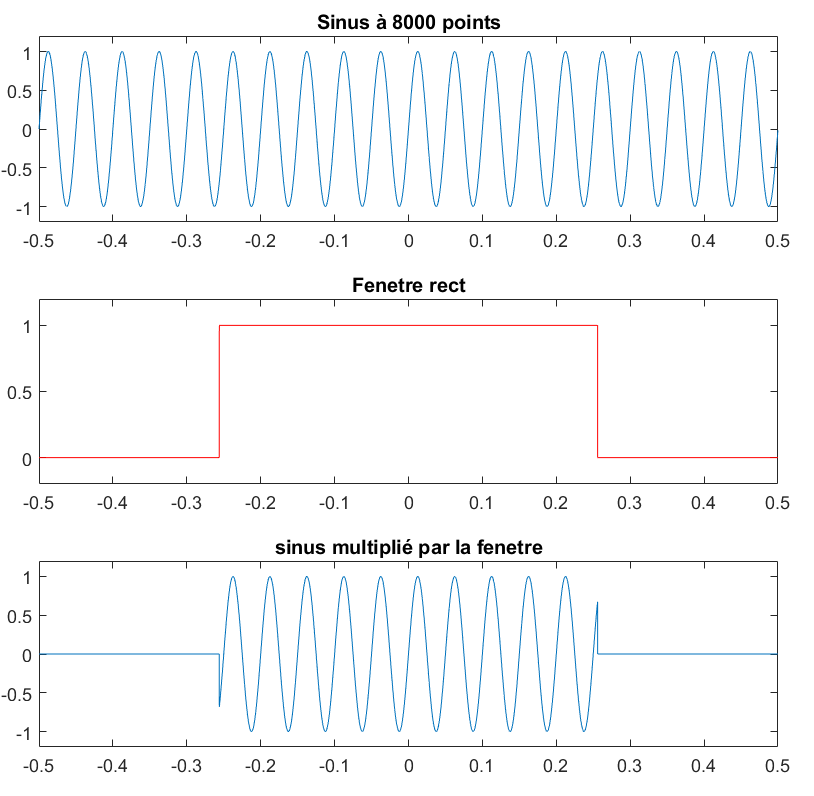

N=8000; % selection de la taille NE PAS MODIFIER LE CODE
%*************************************************************************************
% écrire ici le code qui génère et trace le signal coupé
%*************************************************************************************



Calculer le spectre du signal ainsi formé. **Interprétez**

%*************************************************************************************
% écrire ici le code qui calcule et trace le spectre du signal formé
%*************************************************************************************




Répéter la manœuvre avec une porte de 16000, et 32000 pts tout en gardant 4096 pts à 1 (modifier N dans la liste du code ci dessus). Décrire le comportement du spectre observé pour les différentes tailles.

******************************************************************************************************************

***VOTRE REPONSE ICI***

A votre avis, quel est l’intérêt de rajouter des zéros de part et d’autre du signal acquis ? (On appelle cette manœuvre le *‘zero padding’)*  

******************************************************************************************************************

***VOTRE REPONSE ICI***

  **S’il ne vous reste pas plus d’une heure et demie passez à la partie B ** 

### 4- Fenêtrage

On cherche maintenant à évaluer l’influence des effets de bords de cet échantillonnage de 4096 points. Plutôt que de couper le signal par une porte carrée, on veut travailler la forme de la fenêtre avant le *zero-padding *pour réduire son impact sur le spectre calculé.

On veut étudier l’influence de différentes formes de fenêtres : 

- Rectangulaire (comme celle utilisée jusqu’ici)

- Hamming

- Bartlett  

Tracer ces fenêtres et visualiser leurs spectres (des fonctions Matlab existent pour les calculer). *On pourrait tracer toutes les fenêtres sur un même graphe, puis tous leurs spectres sur un autre graphe.*

%*************************************************************************************
% construction des fenêtres et affichage temporel
%*************************************************************************************
N=8000; 
taille=4096;
t = (-N/2 : ((N/2)-1))/Fe;  

%exemple pour la construction de la fenêtre de Hamming
Hamming=[zeros(1,(N-taille)/2) hamming(taille)' zeros(1,(N-taille)/2) ];

%%%%%%%%%%
%  A FAIRE :construire la fenêtre de Bartlett
%%%%%%%%%%

% affichage
figure;
hold on;
subplot(1,2,1)
plot(t,Hamming);

%%%%%%%%%
% A FAIRE :afficher Bartlett et la fenêtre rectangulaire sur le même
% graphique
%%%%%%%%%

xlabel('Temps') ; ylabel('Amplitude');
title('Fenêtres en temporel');
legend('Hamming'); %compléter les légendes

%*************************************************************************************
% calculs des spectres et affichage fréquentiel
%*************************************************************************************
fHamming=fft(Hamming);
freq=linspace(0,Fe-Fe/N,N); %vecteur frequence
subplot(1,2,2)
plot(freq, abs(fHamming))

%%%%%%%%%
% A FAIRE :afficher la FFT de Bartlett et la fenêtre rectangulaire sur le
% même graphique
%%%%%%%%%

title('Fenêtres en fréqientiel');
xlabel('Fréquence') ; ylabel('Module');
title('Fenêtre en fréquentiel');
legend('Hamming'); %compléter les légendes
axis ([0 20 0 2000]);

**Commenter **les différences observées (en temporel ainsi qu’en fréquentiel)  

******************************************************************************************************************

***VOTRE REPONSE ICI***

Relever les spectres du signal dans le cas où l’on a coupé la sinusoïde par les fenêtres citées ci-dessus puis 0-paddé pour effectuer le calcul de la FFT. (On garde 4096 points pertinents sur les 8000 en total).  

%*************************************************************************************
% ecrire ici le code qui coupe la sinusoide par chacune des trois fenetres
% et affiche les trois spectres
%*************************************************************************************



Conclure sur l’intérêt d’utiliser de telles fenêtres. 

******************************************************************************************************************

***VOTRE REPONSE ICI***

A votre avis, y-a-t-il une fenêtre meilleure que les autres dans l’absolu ? Pourquoi ?  

******************************************************************************************************************

***VOTRE REPONSE ICI***

## Partie B - **Transformée de Fourier en 2D**  

L’analyse de Fourier s’applique aussi pour des signaux à deux dimensions, autrement dit, des images.  

### 5- Calcul de la TF 2D

P=phantom(256); 
figure
imshow(P) ;

Observer la taille de la matrice P et l’étendue de ses valeurs  

fprintf('\nLa taille de la matrice P est de %d x %d', size(P,1), size(P,2));
fprintf('\nLes valeurs de P vont de %d à %d', min(min(P)), max(max(P)));

Le code  suivant vous permet de calculer la transformée de Fourier de P qu’on appellera F et d’en donner sa représentation graphique.  

F=fft2(P) ;
figure;
subplot(1,3,1) ; imagesc(P) ; colorbar ;  axis square; 
subplot(1,3,2) ; imagesc(abs(F)) ; colorbar ; caxis ([0 480]); % ajuster la valeur l'étendue de couleur pour mieux visualisez l'image
axis square;
F=fftshift(F) ;
subplot(1,3,3) ; imagesc(abs(F)) ; colorbar ; caxis ([0 600]); % ajuster la valeur l'étendue de couleur pour mieux visualisez l'image
axis square;

Que permet de faire la fonction *fftshift *? Quel est son intérêt ?  

******************************************************************************************************************

***VOTRE REPONSE ICI***

*L’image de F que vous venez de représenter s’appelle aussi le ****plan ou l’espace de Fourier***  

### 6- Modification de l'espace de Fourier

Dans quelle partie du plan de Fourier sont situées les hautes fréquences ?  

******************************************************************************************************************

***VOTRE REPONSE ICI***

Que représentent les hautes fréquences sur l’image ?  

******************************************************************************************************************

***VOTRE REPONSE ICI***

On se propose de supprimer ces hautes fréquences, ce qui revient à effectuer un filtrage passe bas. En 1D, filtrer un signal avec un passe bas revient à multiplier le domaine fréquentiel par une porte pour garder uniquement les basses fréquences du signal. En 2D cela se fait exactement de la même façon, mais avec une porte 2D.  

Construire une porte rectangulaire 2D et multiplier le plan de Fourier par cette porte  comme dans la figure ci dessous

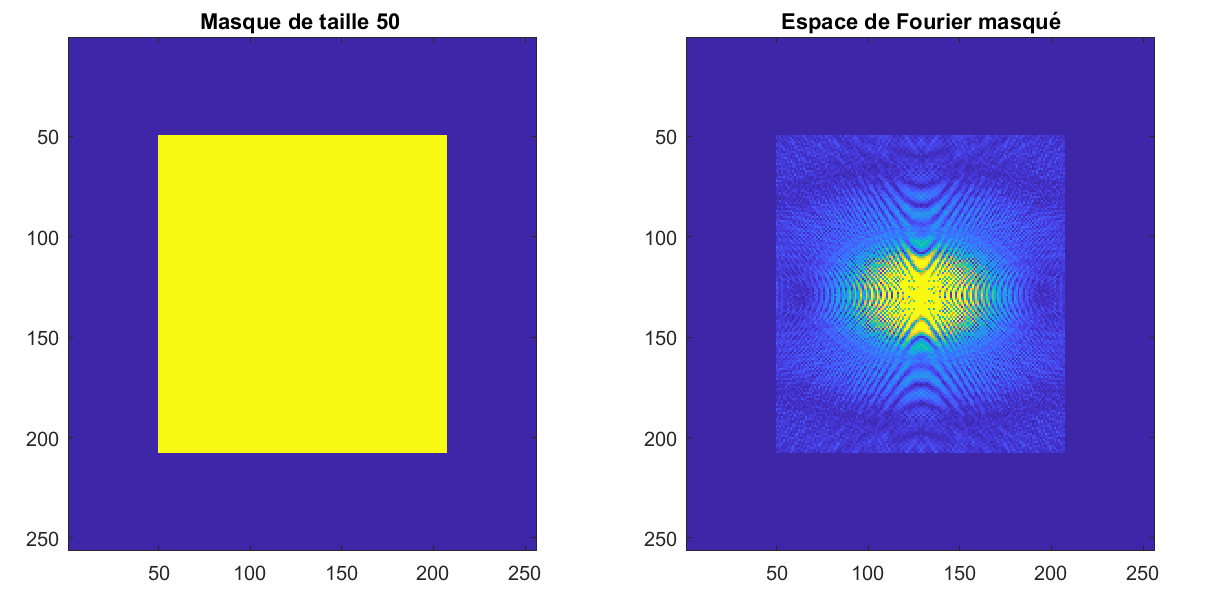

taille = 162; %selection de la taille NE PAS MODIFIER
%*************************************************************************************
% écrire ici le code qui permet de générer la porte de largeur taille et de l'afficher
%*************************************************************************************



*Rappel**: Ayant une matrice A, l’instruction A(i1:i2,j1 :j2)=1 permet de mettre à 1 les éléments de la matrice dont les lignes sont comprises entre i1 et i2 et les colonnes entre j1 et j2  *

%*************************************************************************************
% écrire ici le code qui multiplie le plan de Fourier obtenu précedemment par cette porte et
%affiche le résultat
%*************************************************************************************




Faire la transformée de Fourier inverse du plan masqué pour récupérer une image filtrée dépourvue des variations rapides (hautes fréquences). Modifier la taille de la porte (avec le slider ci dessous) et observer.  

%*************************************************************************************
% écrire ici le code qui calcule et affiche l'image filtrée
%*************************************************************************************



Comparer les images filtrées à l’image de départ. Quel est l’effet du passe bas ?  

******************************************************************************************************************

***VOTRE REPONSE ICI***

En dehors de l’effet de filtrage attendu, un phénomène « indésirable » peut être observé. Lequel ? A votre avis que peut-on faire pour minimiser cet effet de bord ? (il faut juste proposer une idée sans l’appliquer)  

******************************************************************************************************************

***VOTRE REPONSE ICI***

Mettre en place une technique de traitement d’image pour ne voir que les contours de l’image originale. 

%*************************************************************************************
% écrire ici le code qui permet de récuper les contours de l'image P
%*************************************************************************************



**Commenter** le résultat

******************************************************************************************************************

***VOTRE REPONSE ICI***

Mettre à zéro une colonne sur deux du plan de Fourier, et observer l’effet sur l’image  

%*************************************************************************************
% écrire ici le code qui permet de mettre une colonne sur deux du plan de
% fourier et d'observer l'effet sur l'image
%*************************************************************************************



**Commenter** le résultat et **expliquer**  

******************************************************************************************************************

***VOTRE REPONSE ICI***